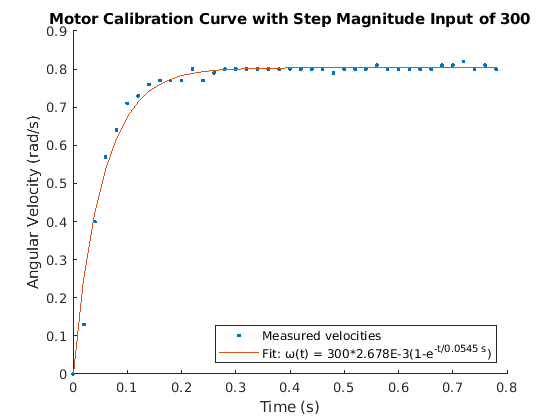

D = readmatrix("calibration_data.csv");
time = linspace(0,.02*(length(D)-1),length(D));
truncate=1:40;
D_trunc = D(truncate,2);
time_trunc = time(truncate);
K = 0.8035;
tau = 0.05451;
clf;hold on
plot(time(truncate),D(truncate,2),".")
plot(time(truncate),K*(1-exp(-time_trunc/tau)))
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")
legend(["Measured velocities", "Fit: ω(t) = 300*2.678E-3(1-e^{-t/0.0545 s})"], "Location", "southeast")
title("Motor Calibration Curve with Step Magnitude Input of 300")

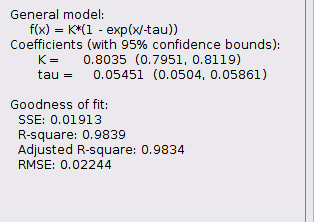

s = 300; %???
kmotor = 0.8035 / s

kmotor = 0.0027

tau = 0.05451

tau = 0.0545

% Rocky_closed_loop_poles.m
%
% 1) Symbolically calculates closed loop transfer function of PI disturbannce
% rejection control system for Rocky. 
% Currently no motor model (M =1).Placeholder for motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki and Kp to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. 
%
% 5) Plot impulse response to see closed-loop behavior. 
%
% based on code by SG. last modified 3/12/21 CL
close all;
syms s a b l g Kp Ki Jp Jicp Ci   % define symbolic variables
Hvtheta = -s/l/(s^2-g/l);       % TF from velocity to angle of pendulum
K = Kp + Ki/s;                % TF of the PI angle controller
J = Jp + Jicp/s + Ci/s^2;
M_o = a*b/(s+a);                 % TF of motor
M = M_o/(1+J*M_o);
% M = 1;                          % TF without motor  
%  
%closed loop transfer function from disturbance d(t)totheta(t)
Hcloop = 1/(1-Hvtheta*M*K)  

$$Hcloop = -\frac{1}{\frac{a\,b\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{l\,\left(\frac{g}{l}-s^{2}\right)\,\left(a+s\right)\,\left(\frac{a\,b\,\left(\mathrm{Jp}+\frac{\text{Ci}}{s^{2}}+\frac{\mathrm{Jicp}}{s}\right)}{a+s}+1\right)}-1}$$

simplify(Hcloop)      % to display the total transfer function

$$ans = -\frac{1}{\frac{a\,b\,s^{2}\,\left(\mathrm{Ki}+\mathrm{Kp}\,s\right)}{\left(g-l\,s^{2}\right)\,\left(a\,s^{2}+s^{3}+\text{Ci}\,a\,b+\mathrm{Jp}\,a\,b\,s^{2}+\mathrm{Jicp}\,a\,b\,s\right)}-1}$$

% Substitute parameters and solve
% system parameters
g = 9.81;
l = 0.45  %effective length 

l = 0.4500

a = 1/tau;           %nomical motor parameters
b = kmotor;        %nomical motor parameters
Hcloop_sub = subs(Hcloop); % sub parameter values into Hcloop
simplify(Hcloop_sub)

$$ans = \frac{1}{\frac{1929942560315836562500\,s^{2}\,\left(\mathrm{Ki}+\mathrm{Kp}\,s\right)}{9\,\left(5\,s^{2}-109\right)\,\left(19299425603158365625\,\text{Ci}+19299425603158365625\,\mathrm{Jicp}\,s+19299425603158365625\,\mathrm{Jp}\,s^{2}+7205759403792793600000\,s^{2}+392785945100745179136\,s^{3}\right)}+1}$$

% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc. 
p1 = -5 + 0.2*pi*i

p1 = -5.0000 + 0.6283i

p2 = -5 - 0.2*pi*i

p2 = -5.0000 - 0.6283i

p3 = -8

p3 = -8

p4 = -1 + 0.2*pi*i

p4 = -1.0000 + 0.6283i

p5 = -1 - 0.2*pi*i

p5 = -1.0000 - 0.6283i

% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increases
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5)

$$tgt\_char\_poly = \left(s+8\right)\,\left(s+1-\frac{\pi \,\mathrm{i}}{5}\right)\,\left(s+1+\frac{\pi \,\mathrm{i}}{5}\right)\,\left(s+5-\frac{\pi \,\mathrm{i}}{5}\right)\,\left(s+5+\frac{\pi \,\mathrm{i}}{5}\right)$$

% get the denominator from Hcloop_sub
[n, d] = numden(Hcloop_sub)

$$n = 9\,\left(5\,s^{2}-109\right)\,\left(19299425603158365625\,\text{Ci}+19299425603158365625\,\mathrm{Jicp}\,s+19299425603158365625\,\mathrm{Jp}\,s^{2}+7205759403792793600000\,s^{2}+392785945100745179136\,s^{3}\right)$$

$$d = 868474152142126453125\,\text{Ci}\,s^{2}-18932736516698356678125\,\mathrm{Jicp}\,s-18932736516698356678125\,\text{Ci}+868474152142126453125\,\mathrm{Jicp}\,s^{3}-18932736516698356678125\,\mathrm{Jp}\,s^{2}+868474152142126453125\,\mathrm{Jp}\,s^{4}+1929942560315836562500\,\mathrm{Ki}\,s^{2}+1929942560315836562500\,\mathrm{Kp}\,s^{3}-7068849975120730521600000\,s^{2}-385323012143831020732416\,s^{3}+324259173170675712000000\,s^{4}+17675367529533533061120\,s^{5}$$

% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s)

$$coeffs\_denom = \left(\begin{array}{cccccc} -18932736516698356678125\,\text{Ci} & -18932736516698356678125\,\mathrm{Jicp} & 868474152142126453125\,\text{Ci}-18932736516698356678125\,\mathrm{Jp}+1929942560315836562500\,\mathrm{Ki}-7068849975120730521600000 & 868474152142126453125\,\mathrm{Jicp}+1929942560315836562500\,\mathrm{Kp}-385323012143831020732416 & 868474152142126453125\,\mathrm{Jp}+324259173170675712000000 & 17675367529533533061120 \end{array}\right)$$

% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end))

$$coeffs\_denom = \left(\begin{array}{cccccc} -\frac{420727478148852370625\,\text{Ci}}{392785945100745179136} & -\frac{420727478148852370625\,\mathrm{Jicp}}{392785945100745179136} & \frac{19299425603158365625\,\text{Ci}}{392785945100745179136}-\frac{420727478148852370625\,\mathrm{Jp}}{392785945100745179136}+\frac{96497128015791828125\,\mathrm{Ki}}{883768376476676653056}-\frac{2180000}{5451} & \frac{19299425603158365625\,\mathrm{Jicp}}{392785945100745179136}+\frac{96497128015791828125\,\mathrm{Kp}}{883768376476676653056}-\frac{109}{5} & \frac{19299425603158365625\,\mathrm{Jp}}{392785945100745179136}+\frac{100000}{5451} & 1 \end{array}\right)$$

% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s)

$$coeffs\_tgt = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{5}\,\left(-5+\frac{\pi \,\mathrm{i}}{5}\right)\,\sigma_{2}\,\sigma_{1} & -\sigma_{2}\,\left(\sigma_{5}\,\sigma_{1}-\sigma_{3}\right)+\sigma_{5}\,\left(-5+\frac{\pi \,\mathrm{i}}{5}\right)\,\sigma_{1} & -\sigma_{5}\,\sigma_{1}+\sigma_{3}-\sigma_{2}\,\left(\sigma_{4}-58+\frac{18\,\pi \,\mathrm{i}}{5}\right) & 58-\sigma_{2}\,\left(-15+\frac{\pi \,\mathrm{i}}{5}\right)-\sigma_{4}-\frac{18\,\pi \,\mathrm{i}}{5} & 20 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-8+\frac{8\,\pi \,\mathrm{i}}{5}\\ \sigma_{2}=5+\frac{\pi \,\mathrm{i}}{5}\\ \sigma_{3}=\left(-5+\frac{\pi \,\mathrm{i}}{5}\right)\,\left(\sigma_{4}-8+\frac{8\,\pi \,\mathrm{i}}{5}\right)\\ \sigma_{4}=\sigma_{5}\,\left(-9+\frac{\pi \,\mathrm{i}}{5}\right)\\ \sigma_{5}=1+\frac{\pi \,\mathrm{i}}{5} \end{array}$$

% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:5) == coeffs_tgt(1:5),  Kp, Ki,Jp,Jicp,Ci)

solutions = struct with fields:
      Kp: [1×1 sym]
      Ki: [1×1 sym]
      Jp: [1×1 sym]
    Jicp: [1×1 sym]
      Ci: [1×1 sym]


% display the solutions as double precision numbers
Kp = real(double(solutions.Kp))

Kp = 1.7399e+03

Ki = real(double(solutions.Ki))

Ki = 8.1332e+03

Jp = real(double(solutions.Jp))

Jp = 33.6777

Jicp = real(double(solutions.Jicp))

Jicp = -516.5722

Ci = real(double(solutions.Ci))

Ci = -264.5432



% Location of the poles of the closed-loop TF.
% NOTE there are only 2 unknowns but 3 polynomial coefficients so 
% the problem is underdetermined and the closed loop poles don't exact
% match the target poles. 
% use trial-and-error to tune response
closed_loop_poles = vpa (roots(subs(coeffs_denom)), 4)

$$closed\_loop\_poles = \left(\begin{array}{c} -0.125\\ -0.1969-0.02474\,\mathrm{i}\\ -0.1969+0.02474\,\mathrm{i}\\ -0.717-0.4505\,\mathrm{i}\\ -0.717+0.4505\,\mathrm{i} \end{array}\right)$$

% Plot impulse response of closed-loop system
    TFstring = char(subs(Hcloop));
    % Define 's' as transfer function variable
    s = tf('s');
    % Evaluate the expression
    eval(['TFH = ',TFstring]);

TFH =
 
                                
  4.614e77 s^8 + 1.769e79 s^7   
                                
          + 1.475e80 s^6        
                                
          - 6.066e80 s^5        
                                
          - 3.545e81 s^4        
                                
          + 4.814e81 s^3        
                                
                  + 2.399e81 s^2
                                
  ------------------------------
                                
  4.614e77 s^8 + 1.769e79 s^7   
                                
          + 2.352e80 s^6        
                                
          + 1.411e81 s^5        
                                
          + 3.972e81 s^4        
                                
          + 4.814e81 s^3        
                                
                  + 2.399e81 s^2
                                
 
Continuous-time transfer function.



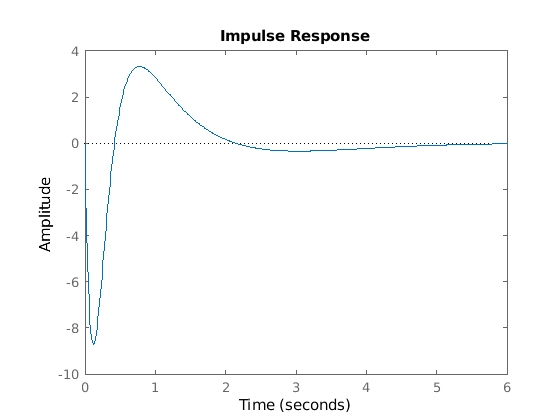

    figure (1)
    impulse(TFH);   %plot the impulse reponse

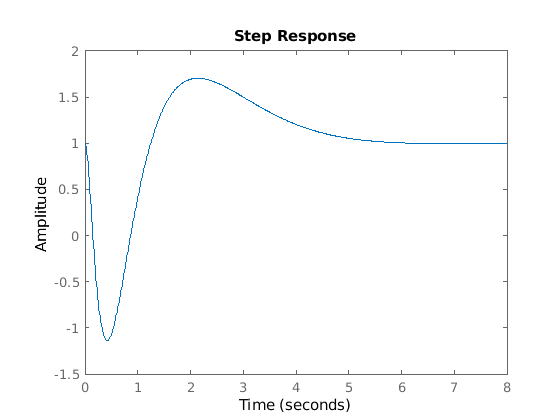

    figure(2)
    step(TFH)